## **Forward TRF - comparing datasets example**

This is a follow-up of the ForwardTRF example. Please refer to that script for documentation and explanations on the forward TRF.

This script provides an example comparison of distinct datasets. This may be done for various reasons, such as replicating results, comparing experimental setups, conditions, or participants cohorts. TRF analyses would typically be run on individual participants. For reducing computational requirements in this example, I shared 'virtual' participants calculated by averaging the EEG signal from all participants within each dataset. Please note that this is not optimal and it is only appropriate for simplifying the computational and code complexity of this example.

Here, we consider a melody listening dataset (diliBach), an audio-book listening dataset (LalorNatSpeech), and a cocktail party attention switching datasets (cocktailAttSwitch). Please refer to [https://cnspworkshop.net/resources.html](https://cnspworkshop.net/resources.html) for information on the authors and appropriate references, as well as for in-depth documentation.

'dataStim.mat' contains the stimulus features. 'pre_dataSubAvg.mat' contains the preprocessed EEG signals. Then, the script runs a typical forward TRF analysis to measure how strongly the EEG signals encode specific stimulus features, comparing the various datasets.

Note: Please see [https://cnspworkshop.net](https://cnspworkshop.net) and [https://diliberg.net](https://diliberg.net) for additional resources such as tutorials, videotutorials, and datasets.

Author: Giovanni M. Di Liberto ([https://diliberg.net](https://diliberg.net)) 

Please cite:

- mTRF-Toolbok: [https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full](https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full) 

- Open science framework: [https://nbdt.scholasticahq.com/article/124867-a-standardised-open-science-framework-for-sharing-and-re-analysing-neural-data-acquired-to-continuous-stimuli](https://nbdt.scholasticahq.com/article/124867-a-standardised-open-science-framework-for-sharing-and-re-analysing-neural-data-acquired-to-continuous-stimuli) 

Please check out

- mTRF-Toolbox - Considerations for applied research: [https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full](https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full) 

- Original study for the diliBach dataset: [https://elifesciences.org/articles/51784](https://elifesciences.org/articles/51784) 

- CND dataset available here: [https://cnspworkshop.net/resources.html](https://cnspworkshop.net/resources.html) 

### Workspace setup

This section clears the workspace and adds the library folders to the Matlab paths

clear all
close all

addpath ./libs/cnsp_utils
addpath ./libs/cnsp_utils/cnd
addpath ../mtrf
addpath ./libs/fileDownload

disp('Forward TRF - compare datasets example live-script')

Forward TRF - compare datasets example live-script


### Data preparation

This section downloads the sample data. This sample dataset consists of 64-channel EEG time-series from two distinct individuals (pre_dataSub files; note that the original dataset includes data from 20 participants). The signals were filtered between 1 and 8 Hz and downsampled to 64Hz. The dataStim.mat file contains features of the corresponding music stimulus (i.e., Hilbert envelope and note onsets). dataStim is the input of a forward mTRF model. dataSub is the output of a forward mTRF model.

% Downloading and pre-loading data
datasetNames = {'LalorNatSpeech','diliBach','cocktailAttSwitch'};

clear eegAll stimAll stimNames
for iiDataset = 1:length(datasetNames)
    datasetName = datasetNames{iiDataset};
    
    % Creating directory where the sample data will be downloaded
    if ~exist(datasetName, 'dir')
        mkdir(datasetName)
    end
    
    % Setting up filenames and URL
    stimFilename = "dataStim.mat";
    eegFilenames = {'pre_dataSubAvg.mat'};
    
    dataStim_URL = "https://www.data.cnspworkshop.net/sampleData/"+datasetName+"/"+stimFilename;
    
    % Download stimulus file
    if ~isfile(datasetName+"/"+stimFilename)
        downloadFile(datasetName+"/"+"dataStim.mat", dataStim_URL, ShowFilename=true)
    else
        disp('Skipping download. Stim file already present.')
    end

    % Download neural data file
    iiSub = 1;
    dataSub_URL = "https://www.data.cnspworkshop.net/sampleData/"+datasetName+"/"+eegFilenames{iiSub};

    if ~isfile(datasetName+"/"+eegFilenames{iiSub})
        downloadFile(datasetName+"/"+eegFilenames{iiSub}, dataSub_URL, ShowFilename=true)
    else
        disp('Skipping download. EEG file already present.')
    end
    nSubs = length(eegFilenames);

    % Loading EEG
    eegFilename = datasetName+"/"+eegFilenames{iiSub}; 
    load(eegFilename,'eeg')
    eeg = cndNormalise(eeg); % Standardise neural data (preserving the ratio between channels)

    % Loading Stimulus data
    stimFilename = datasetName+"/"+"dataStim.mat";
    load(stimFilename,'stim')
    
    stim = cndNormalise(stim);
    
    % Load list of stimulus features
    stimNames{iiDataset} = stim.names;

    % Validation of dataset sampling rate and size
    if eeg.fs < stim.fs
        stim = cndDownsample(stim,eeg.fs);
    end
    [stim,eeg] = cndCheckStimNeural(stim,eeg);

    % Store EEG and stim
    stimAll{iiDataset} = stim;
    eegAll{iiDataset} = eeg;
end

Skipping download. Stim file already present.


Skipping download. EEG file already present.


Processing CND: Downsampling from fs = 128 to downFs = 64


Skipping download. Stim file already present.


Skipping download. EEG file already present.


Skipping download. Stim file already present.


Skipping download. EEG file already present.


### Forward mTRF model fit

Setting up mTRF hyperparameters

tmin = -200;
tmax = 550;
lambdas = 10.^(-4:2:4); % small set of lambdas (quick)
dirTRF = 1; % Forward TRF model
stimIdx = 1; % The first feature is the envelope for all the selected datasets

tmax = max(tmax,tmin);


Cross validation and hyperparameter tuning for all datasets

clear rAll bestLambdaAll
for iiDataset = 1:length(eegAll)
    disp("Crossvalidation dataset "+iiDataset+"/"+length(eegAll))
    stim = stimAll{iiDataset};
    eeg = eegAll{iiDataset};

    [stats,t] = mTRFcrossval(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);
        
    % Calculating optimal lambda. Display and store results
    [maxR,bestLambda] = max(squeeze(mean(mean(stats.r,1),3)));
    disp(['r = ',num2str(maxR)])
    rAll(iiDataset) = maxR;
    bestLambdaAll(iiDataset) = bestLambda;
end

Crossvalidation dataset 1/3


r = 0.026434


Crossvalidation dataset 2/3


r = 0.073282


Crossvalidation dataset 3/3


r = 0.027356


clear modelAll
for iiDataset = 1:length(eegAll)
    disp("TRF model fit dataset "+iiDataset+"/"+length(eegAll))
    stim = stimAll{iiDataset};
    eeg = eegAll{iiDataset};

    % Fit TRF model with optimal regularisation parameter
    model = mTRFtrain(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas(bestLambdaAll(iiDataset)),'verbose',0);
    
    % Store TRF model
    modelAll(iiDataset) = model;
end

TRF model fit dataset 1/3
TRF model fit dataset 2/3
TRF model fit dataset 3/3


Plot comparing forward envelope TRFs

disp("Forward TRF weights")

Forward TRF weights


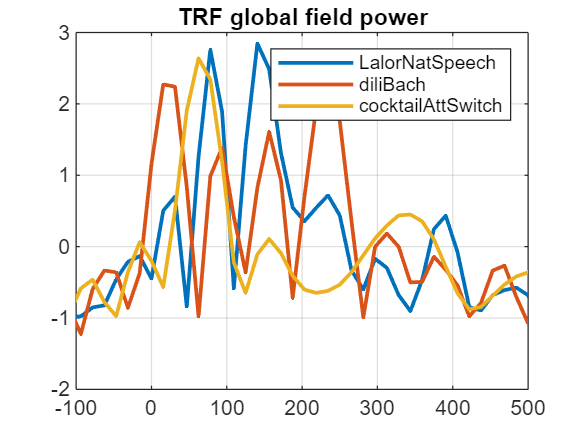


clear gfpAll
for iiDataset = 1:length(modelAll)
    gfpAll(iiDataset,:) = std(squeeze(modelAll(iiDataset).w)');
end

figure;
plot(modelAll(1).t,zscore(gfpAll'),'LineWidth',1.5)
title('TRF global field power')
xlim([-100,500])
legend(datasetNames)
grid on

The figure shows the global field power for the three datasets. This might differ from published results as it was calculated only on the 'virtual' average participants, while it would me appropriate to work with the individual participants instead. Nonetheless, this result gives a graphical intuition of what kind of observarious one could make. For example, the TRF components broadly occur within 0 and 300 ms for all datasets, with quite a few differences between datasets though. Observing the single EEG channels would also be appropriate, for instance using butterfly plots, single-channel analyses, and topographies. 